# Modelo cinemático de un robot móvil

clear all;
clc;
close all;

% parameters
rR=0.075;
rL=rR;
b=0.3/2;
tf=3; %Duración total de la simulación

#### Simulación por el método de euler

% time vector and time increment
t=linspace(0,tf,60);
dt=t(2)-t(1);

#### Condiciones inciales

% initial conditions
theta0=pi/2;
x0=0.5;
y0=0.5;

#### Parámetros de entrada

%Velocidades de cada una de las ruedas
phi1p=80; %revs/min
phi2p=100; %revs/min

#### Inicio de la integración numérica

% Creación de los vectores para almacenar POSE de cada iteración
x=zeros(1,length(t));
y=zeros(1,length(t));
theta=zeros(1,length(t));
theta(1)=theta0;
x(1)=x0;
y(1)=y0;

% Creación de los vectores de velocidad de cada rueda en cada iteracion(RPM a rad/s)
ind=find(t<=max(t)/3);
vec=ones(1,length(t));
Velocidad_1=phi1p*(2*pi/60)*(vec(ind));
velocidad_2=phi2p*(2*pi/60)*(vec(ind));
phidotR=[Velocidad_1 Velocidad_1 Velocidad_1]; %Rueda 1
phidotL=[velocidad_2 velocidad_2 velocidad_2]; %Rueda 2

%Bucle de actualización de coordenadas generales
for ii=2:length(t)
    J=[rR*cos(theta(ii-1))/2 rL*cos(theta(ii-1))/2;...
        rR*sin(theta(ii-1))/2 rL*sin(theta(ii-1))/2;...
        0.5*rR/b -0.5*rL/b]; %Matriz jacobiana (relaciona las velocidades de las ruedas con el movimiento del robot)
    deltapose=dt*J*[phidotR(ii-1);phidotL(ii-1)]; %Vector de cambio de posición [x;y;theta]
    x(ii)=x(ii-1)+deltapose(1);
    y(ii)=y(ii-1)+deltapose(2);
    theta(ii)=theta(ii-1)+deltapose(3);
end
x(ii)

ans = 1.8319

y(ii)

ans = 1.8679

theta(ii)

ans = 5.9674e-16

#### Animación

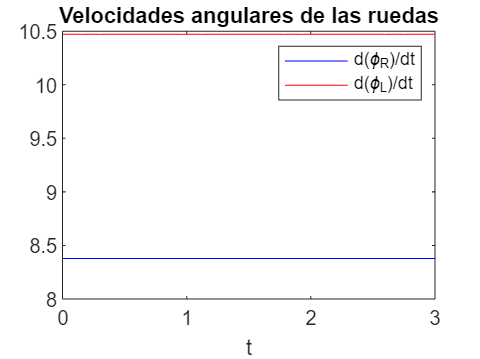

% Simulación y Animación
figure(1);
plot(t,phidotR,'b');
hold on;
plot(t,phidotL,'r');
xlabel('t')
legend('d(\phi_{R})/dt','d(\phi_{L})/dt')
title('Velocidades angulares de las ruedas');

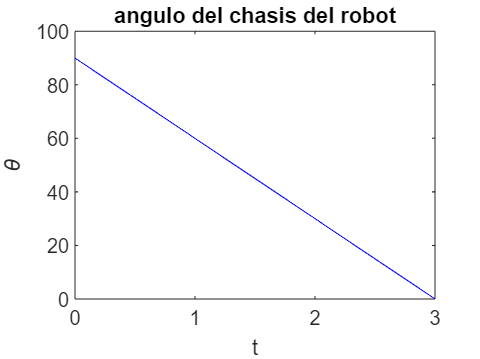


figure(2);
plot(t,rad2deg(theta),'b');
xlabel('t')
ylabel('\theta')
title('angulo del chasis del robot');

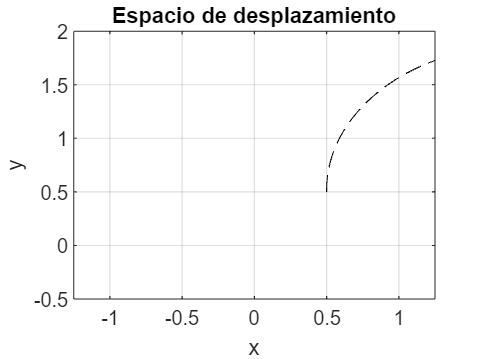


figure(3);
plot(x,y,'k--');
title('Espacio de desplazamiento')
xlabel('x')
ylabel('y')
hold on;
wls=[0 0;-0.5*b 0.5*b];
wlsrot=[cos(theta(ii)) -sin(theta(ii));sin(theta(ii)) cos(theta(ii))]*wls;
h1=plot(wlsrot(1,1)+x(1),wlsrot(2,1)+y(1),'ro','LineWidth',2,'MarkerFaceColor','r');
h2=plot(wlsrot(1,2)+x(1),wlsrot(2,2)+y(1),'ro','LineWidth',2,'MarkerFaceColor','r');
h3=plot(x(1),y(1),'bo','MarkerSize',20);
grid on
axis([-1.25 1.25 -0.5 2]);

for ii=2:length(t)
    wlsrot=[cos(theta(ii)) -sin(theta(ii));sin(theta(ii)) cos(theta(ii))]*wls;
    set(h1,'XData',wlsrot(1,1)+x(ii));
    set(h1,'YData',wlsrot(2,1)+y(ii));
    set(h2,'XData',wlsrot(1,2)+x(ii));
    set(h2,'YData',wlsrot(2,2)+y(ii));
    set(h3,'XData',x(ii));
    set(h3,'YData',y(ii));
    
    drawnow;
    pause(0.1);
end